clear all
load TR4_data.mat
S=[[5.7426 4 -2.4142]',[9.0487 5.5871 2.7189]'];

[Ql,Qpl,Qppl,Tl,Xl]=TR4_linearMov(S,@Cicloidale,5,link);

ans = 2

qp=diff(Ql(1,:,3))/(Tl(2)-Tl(1))

qp =    -0.0002   -0.0016   -0.0043   -0.0084   -0.0138   -0.0205   -0.0286   -0.0380   -0.0488   -0.0609   -0.0745   -0.0895   -0.1060   -0.1240   -0.1438   -0.1653   -0.1887   -0.2140   -0.2416   -0.2715   -0.3038   -0.3388   -0.3766   -0.4174   -0.4611   -0.5078   -0.5574   -0.6093   -0.6629   -0.7170   -0.7695   -0.8176   -0.8570   -0.8821   -0.8866   -0.8646   -0.8145   -0.7417   -0.6587   -0.5787   -0.5105   -0.4567   -0.4159   -0.3856   -0.3630   -0.3461   -0.3332   -0.3231   -0.3150   -0.3083


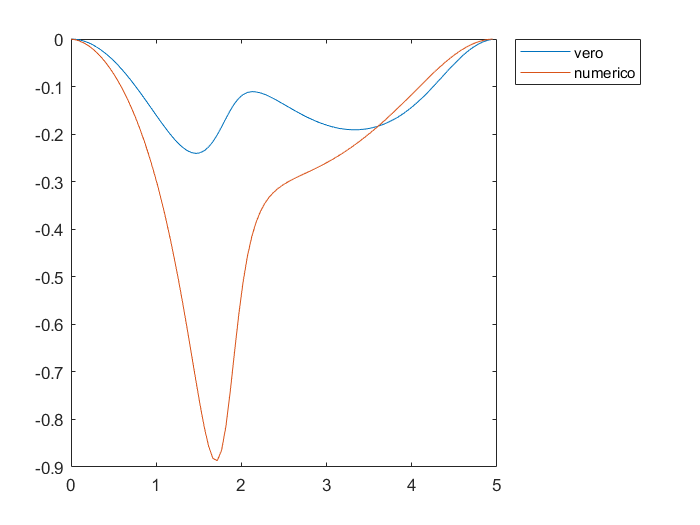

plot(Tl(1:end-1),Qpl(1,1:end-1,3),Tl(1:end-1),qp)
legend("vero","numerico")

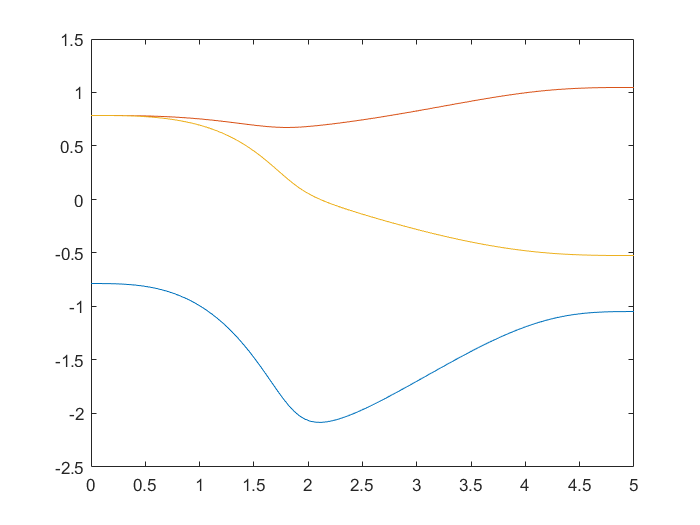

plot(Tl,Ql(1,:,1),Tl,Ql(1,:,2),Tl,Ql(1,:,3))

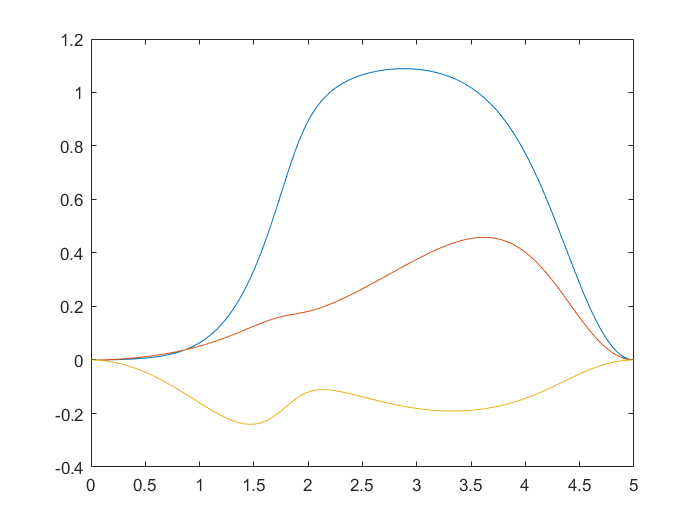

plot(Tl,Qpl(1,:,1),Tl,Qpl(1,:,2),Tl,Qpl(1,:,3))

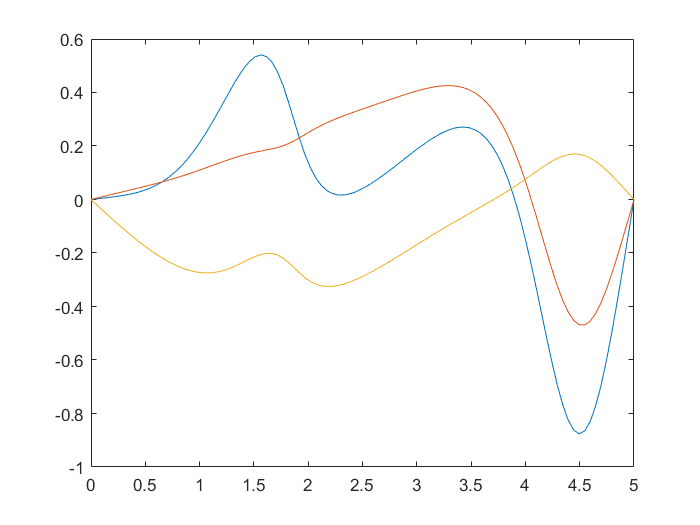

plot(Tl,Qppl(1,:,1),Tl,Qppl(1,:,2),Tl,Qppl(1,:,3))

Q1=TR4_invNumeric(S(:,1)',[0.5 0.5 0.5],link,1000);
Q2=TR4_invNumeric(S(:,2)',[0.5 0.5 0.5],link,1000);
Q=[Q1,Q2]

Q =    -0.7854   -1.0472
    0.7854    1.0472
    0.7854   -0.5236


[X,T,Qj] = TR4_jointMov(Q,@Cicloidale,5,link);

ans = 2

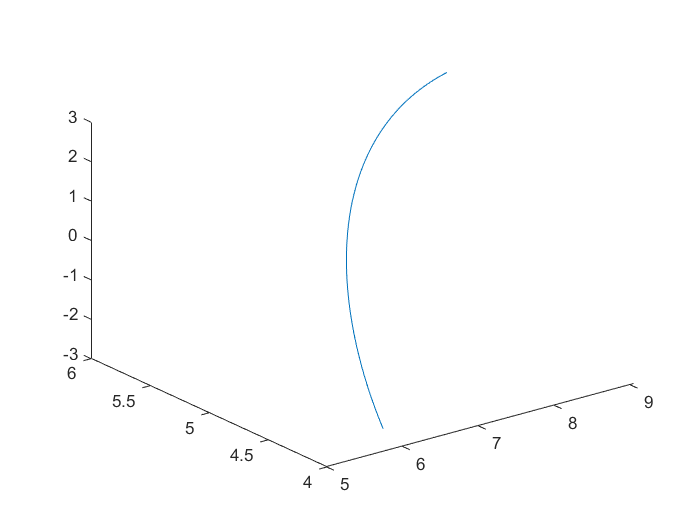

plot3(X(1,:,1),X(1,:,2),X(1,:,3))

save traiettoria_test X Ql T Q S